# **Stochastic Gridworld Environment with Deep Q-Learning Agent**

In this module we cover stochastic environments and how a Deep Q learning agent is generated and trained. In the previous module we saw how to use and update the pre defined enviornment functions in MATLAB. This module is more focused on using and exploring Reinforcement Learning designer App for creating and training a DQN agent.

- Create a Stochastic Gridworld environment using an edited MATLAB function

- Model, define and initialize a Deep Q-Learning Agent

- Using Reinforcement Learning Designer App

Please go though the supplementary file named 'Reason to use Deep Learning Agents' before you start with this module.

## **Problem Formulation**

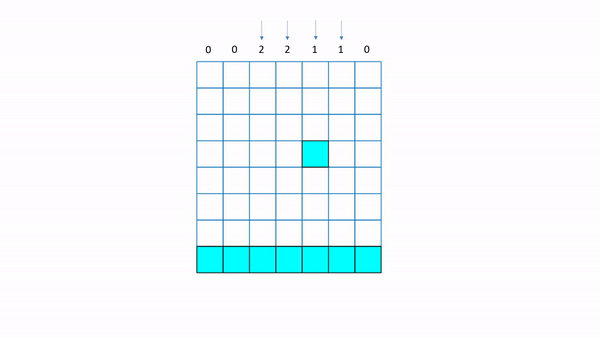

**Goal: **Reach the nearest **positive** terminal states as quickly as possible

**Actions:** The agent can move in 4 possible directions

**States:** There are 56 states with 7 Positive Terminal (8th Row) and 1 Negative Terminal state (4,5)

**Reward: **All nonterminal states have a small negative reward (-1) and terminal states have a large positive reward (10)

**Assumptions:**

- Agent has to move around, cannot stop at one place.

- The stochasticity in the environment affects the agents movement.

- The environment pushes the agent towards the bottom of the grid with a given intensity

- If the agent goes up from state [4,2], it will land in state [6,2]

## **Creating the Environment**

**TASK: Go through the pre defined MATLAB enviornment 'WaterFallGridWorld-Stochastic'**

Use function [`rlPredefinedEnv(keyword)`](https://www.mathworks.com/help/reinforcement-learning/ref/rlpredefinedenv.html#d123e8264),which takes an input that is keyword for environment defined.

%Start you code ~ one line
%Code ends here

ans =   GridWorld with properties:

          GridSize: [8 7]
      CurrentState: "[5,1]"
            States: [56×1 string]
           Actions: [4×1 string]
                 T: [56×56×4 double]
                 R: [56×56×4 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [8×1 string]


Vizualize the environment using plot funtion

%Start you code ~ one line
%Code ends here

ans = ans(:,:,1) =

    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

ans = ans(:,:,1) =

    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    10    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10
    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    10    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10
    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1    10    -1    -1    -1   -10    -1    -1    -1    -1    -1    -1    -1   -10    -1    -1    -1

ans = 4×1 string array
    "N"
    "S"
    "E"
    "W"


Access pre-defined properties of the in-biult environment using dot notation

%Start you code ~ one line
%Code ends here

- Show the Transition Probabilities 

- Show the Reward

- Show the Actions

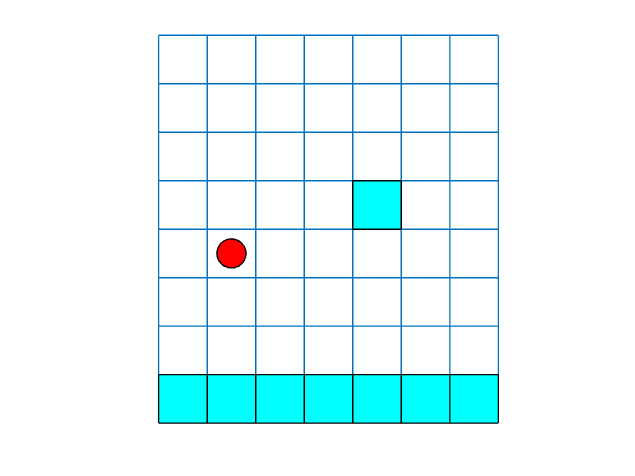

ans = 13

%Start you code ~ two lines

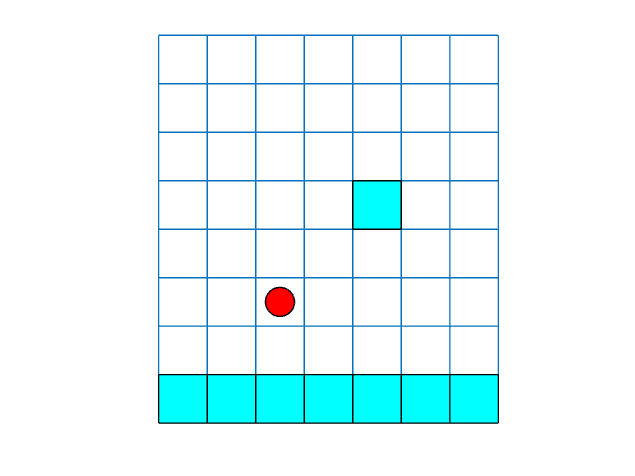

ans = 22

%Code ends here

Use the step function to vizualize behavior of an agent in the enviornment

Move the agent from position to (5,1) to (5,2). What do you notice regarding the selected action and landed state?

Use the dot notation to access the step function of the environment. step function takes in an Input of the action that the agent needs to perform.

Here the action E indexed at position 3 will move the agent towards left to state (5,2)

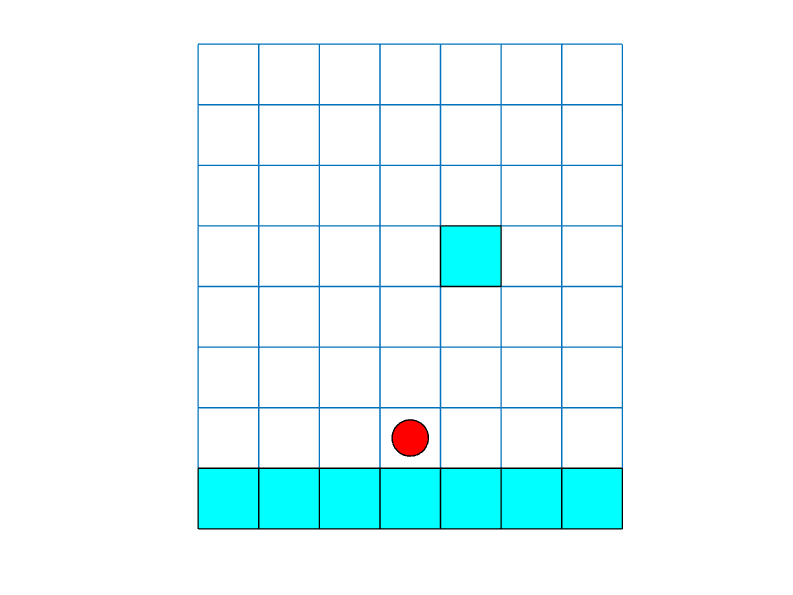

ans = 31

%Start your code here
%end your code here

Move the agent from position to (5,2) by taking action East. What do you notice regarding the selected action and landed state?

%Start your code here
%Code ends here

Move the agent from position to (5,3) by taking action East. What do you notice regarding the selected action and landed state?

%Start your code here
%Code ends here

## **Creating an Agent**

We have now seen how our environments behaves, let us move on to see how to construct and model a Deep Q learning agent. 

This can be done in following ways -

- Using Reinforcement Learning Designer app.

- Using RL toolbox agent functions (Like module 1)

- Modeling our own agent using Deep Designer App.

In this module we use method 1 : ***Using Reinforcement Learning Designer app for initiazing agent***

## Method 1: Using Reinforcement Learning Designer app for initiazing agent.

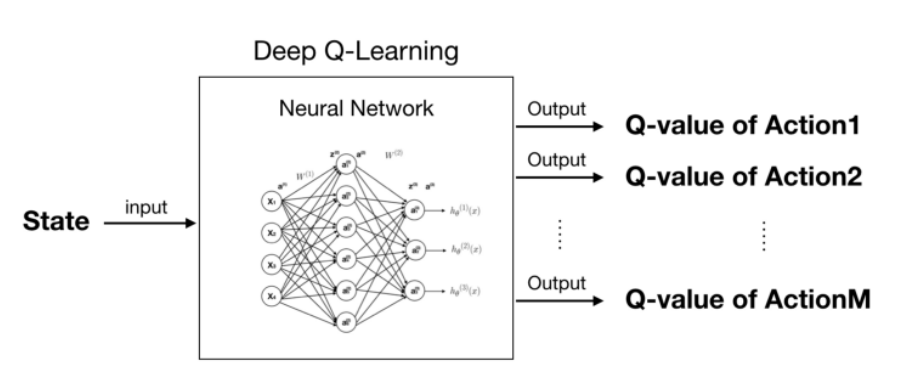

Like a Q leaning agent, Deep Q Leaning agent is a model-free, online, off-policy reinforcement learning agent. Instead of table, we have a neural network as function approximator to map relation between input (States) and output (State- Action Values).

Let us open the Reinforcement Learning Designer App. Simply type in ' reinforcementLearningDesigner '. Or select Apps tab from the ribbion above.

Please visit [this ](https://www.mathworks.com/help/reinforcement-learning/ug/create-agents-using-reinforcement-learning-designer.html)page for more information

%Start your code here

%Code ends here

agent =   rlDQNAgent with properties:

        AgentOptions: [1×1 rl.option.rlDQNAgentOptions]
    ExperienceBuffer: [1×1 rl.util.ExperienceBuffer]


critic =   rlQValueRepresentation with properties:

         ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
    ObservationInfo: [1×1 rl.util.rlFiniteSetSpec]
            Options: [1×1 rl.option.rlRepresentationOptions]


parameters = 6×1 cell array
    {256×1   single}
    {256×1   single}
    {256×256 single}
    {256×1   single}
    {  4×256 single}
    {  4×1   single}


Follow the images and steps to train your agent:

**Step 1: **Click on the Import button to load the environment stored in the variable env

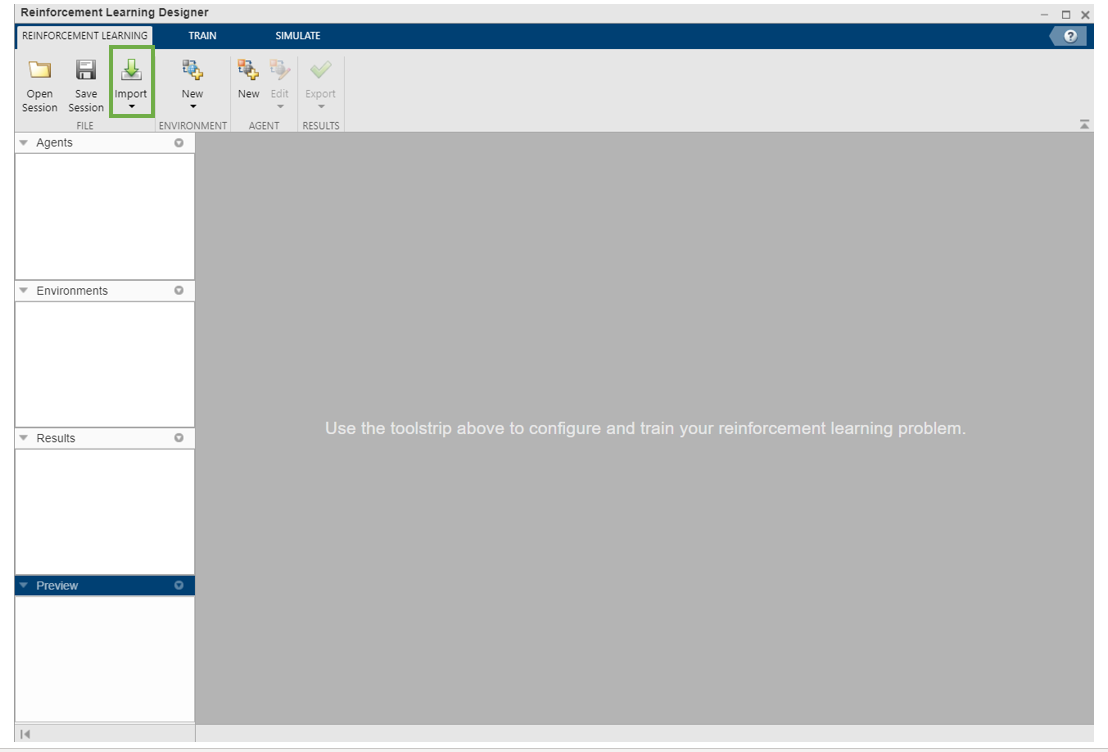

**Step 2**: Click on the env loaded in the Environment pane. This will populate the Preview Pane as well.

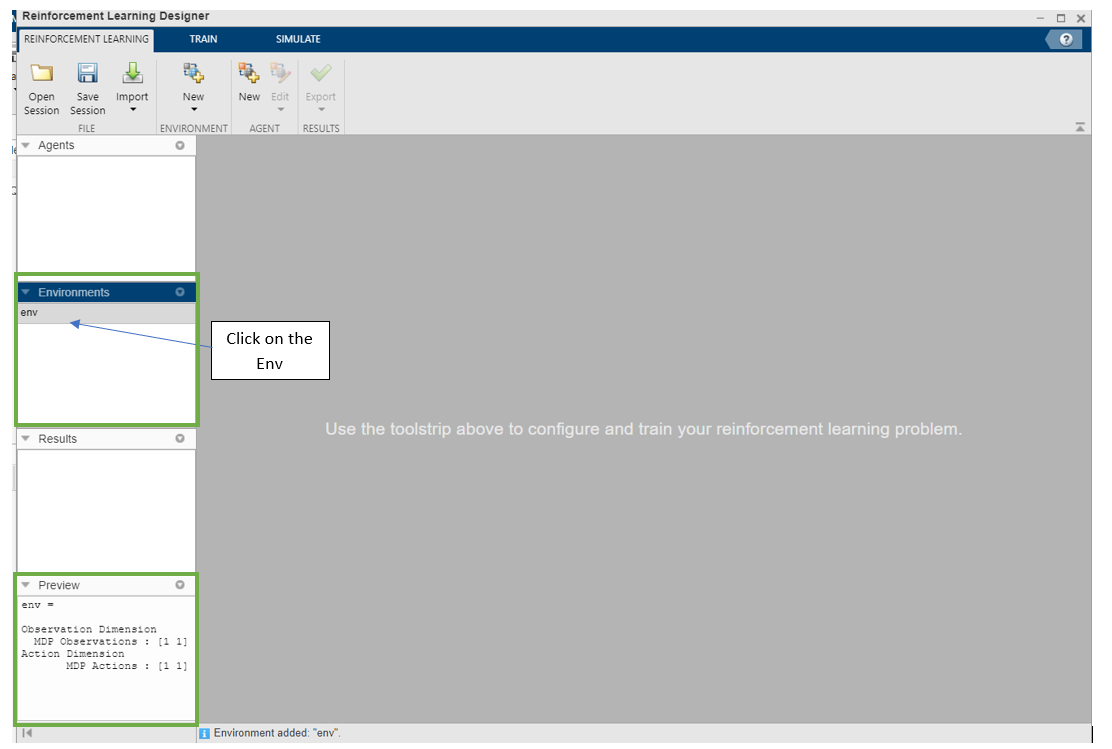

**Step 3**: Creating an Agent.

This is similar to using RL Toolbox function - [`rlDQNAgent(observationInfo,actionInfo)`](https://www.mathworks.com/help/reinforcement-learning/ref/rldqnagent.html#d123e17832)

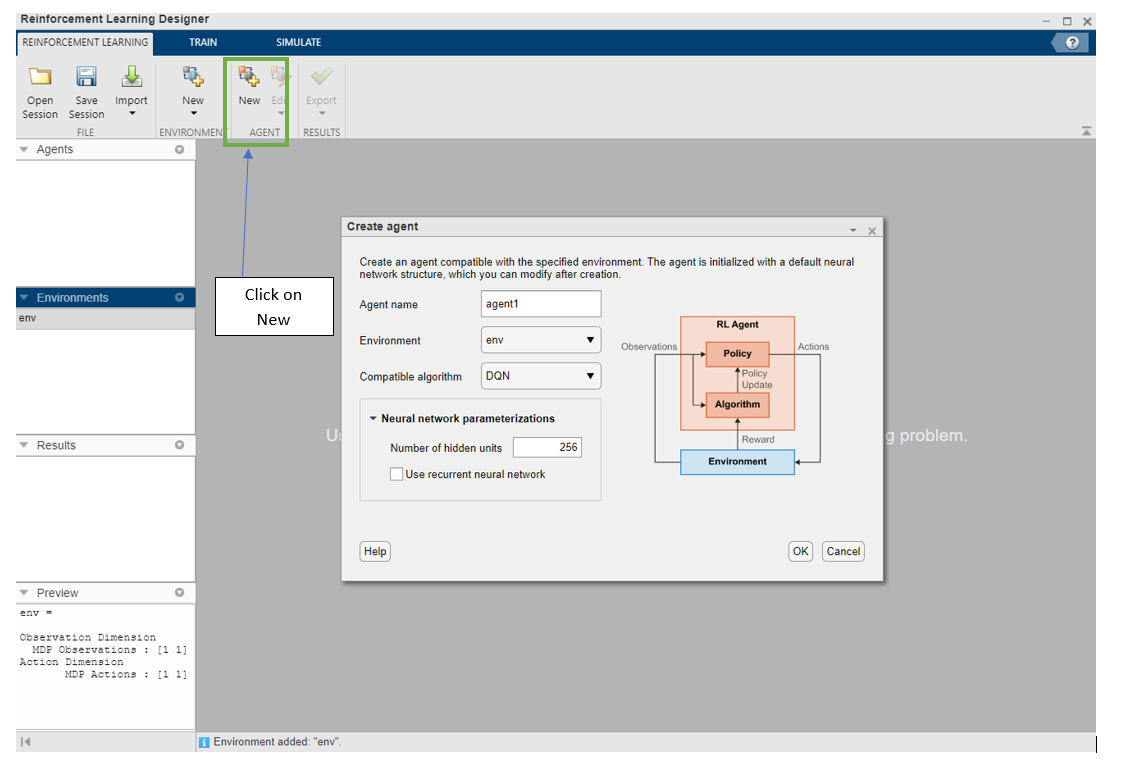

In the Create Agent window following options can be modified:

*Agent Name*- Name your agent

*Environment* - Select the environment on which you want to train your agent

*Compatible Algorithm* - Select a training algorithm that will be used for updating the agent's learning process

Hit **OK** once the editing is done.

**Step 4:**  Visualizing  the neural network of agent created

Select the agent in Agent pane

Click on the View Critic Model

Close the Window once done

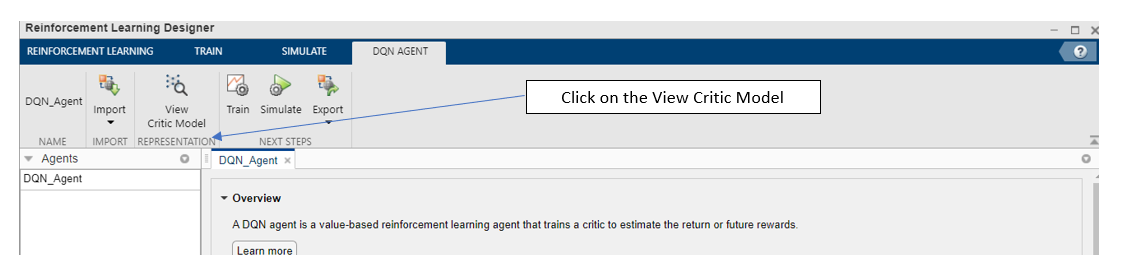

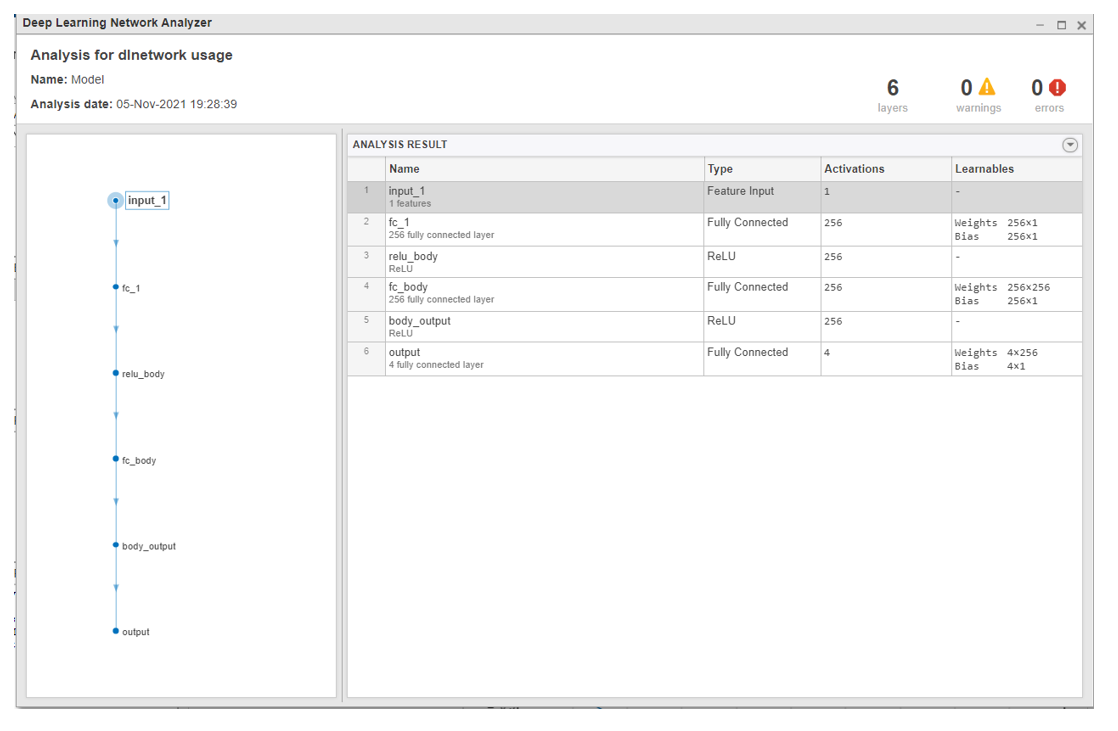

- Input Layer - Feature Input Layer -- with one input. With every step the agent lands in next state (grid location denatoed by s1, s2, s3,...s56)

- Two Fully connected hidden layer with 256 nuerons each. These layers are then fitted with ReLu actiovation function

- Output Layer - Fully connected with neurons equal to number of action i.e 4

**Step 5: **Click on the Agent name in Agent Pane(Window) then click on Train button in tabs at the top.

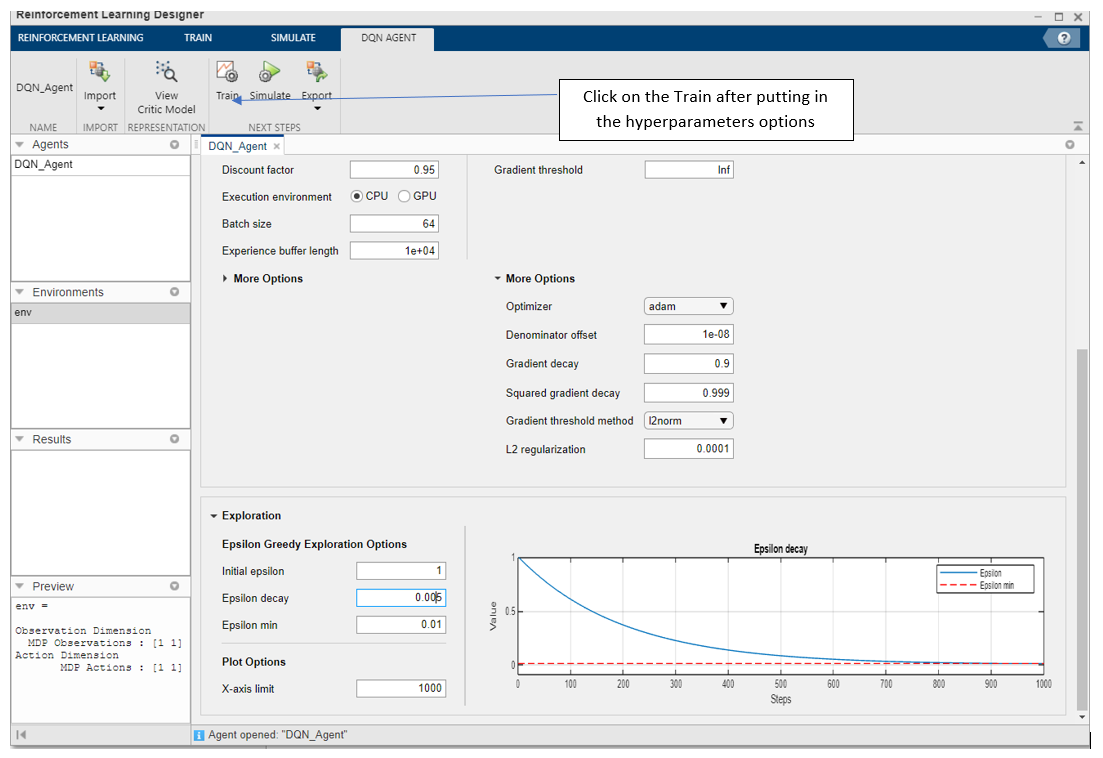

**Step 6: **In this step we specify -

- Agent Leaning Parameters such as (Learn Rate, exploration rate, Episollin decay)

- Training parameters such as (Episode, Stopping criteria, etc)

This is similar to using RL toolbox functions - [`rlDQNAgentOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rldqnagentoptions.html)`, `[`rlQValueRepresentation`](https://www.mathworks.com/help/reinforcement-learning/ref/rlqvaluerepresentation.html)`, ` [`rlTrainingOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rltrainingoptions.html).

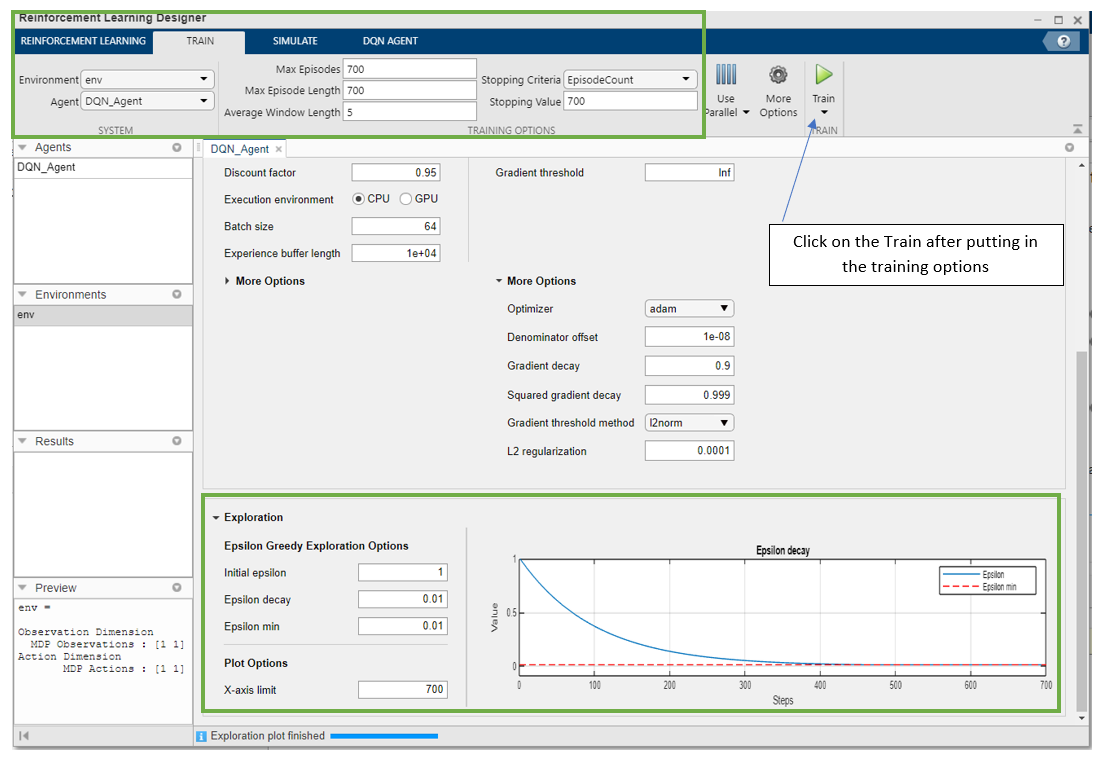

**Step 7: **Analyzing Training Process

The training information is seen on the right side of the window.

Click on the Acceot result button to store the training hyper parameters. This trained agent can now be used to simulate in an environment or if nesecarry put into re-training process.

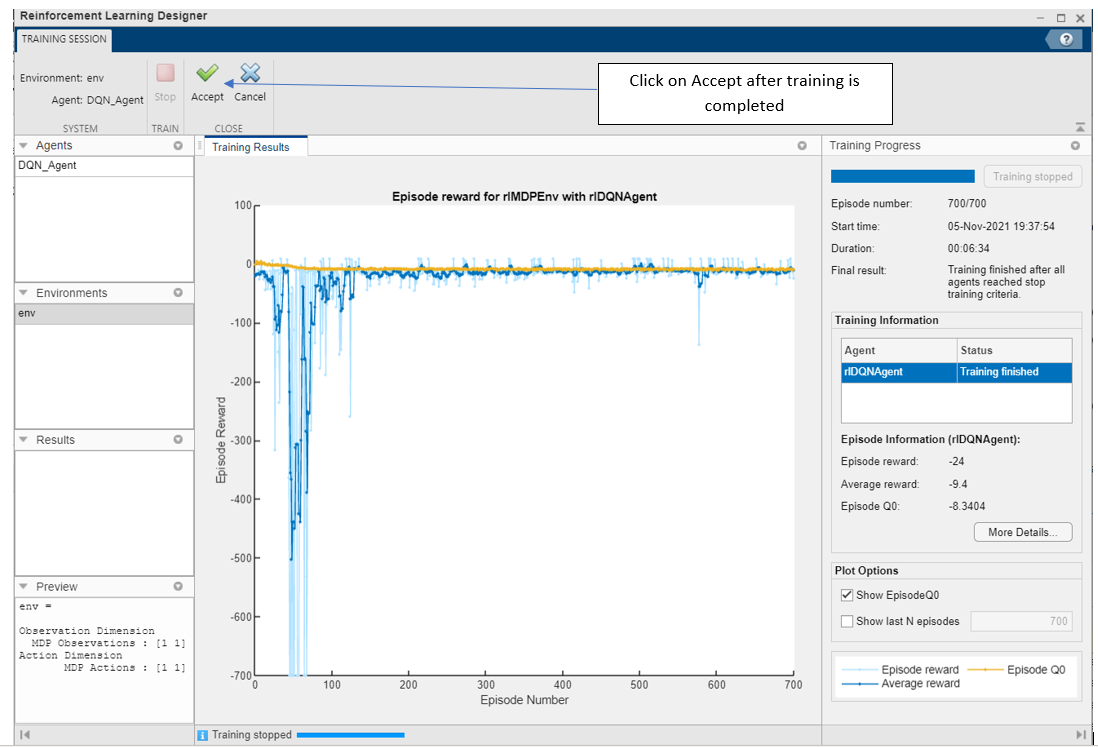

**Step 8**: Simulate the trained agent

This is similar to using RL Toolbox functions [`rlSimulationOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rlsimulationoptions.html) and [`sim`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.abstractenv.sim.html).

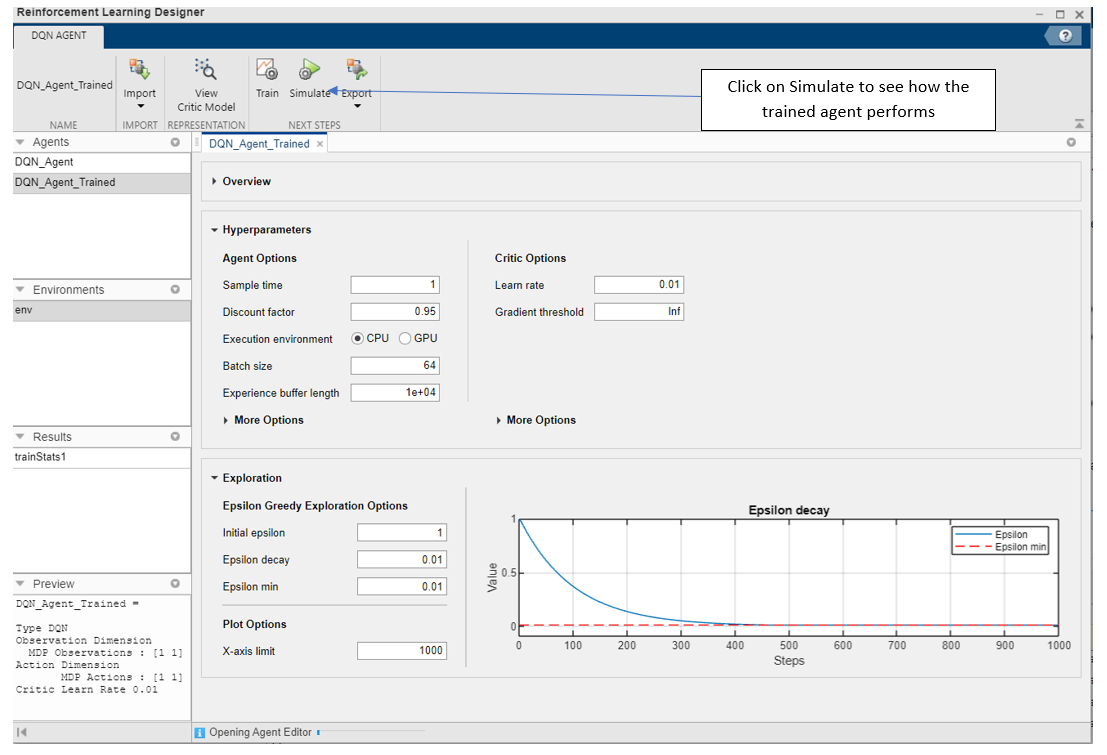

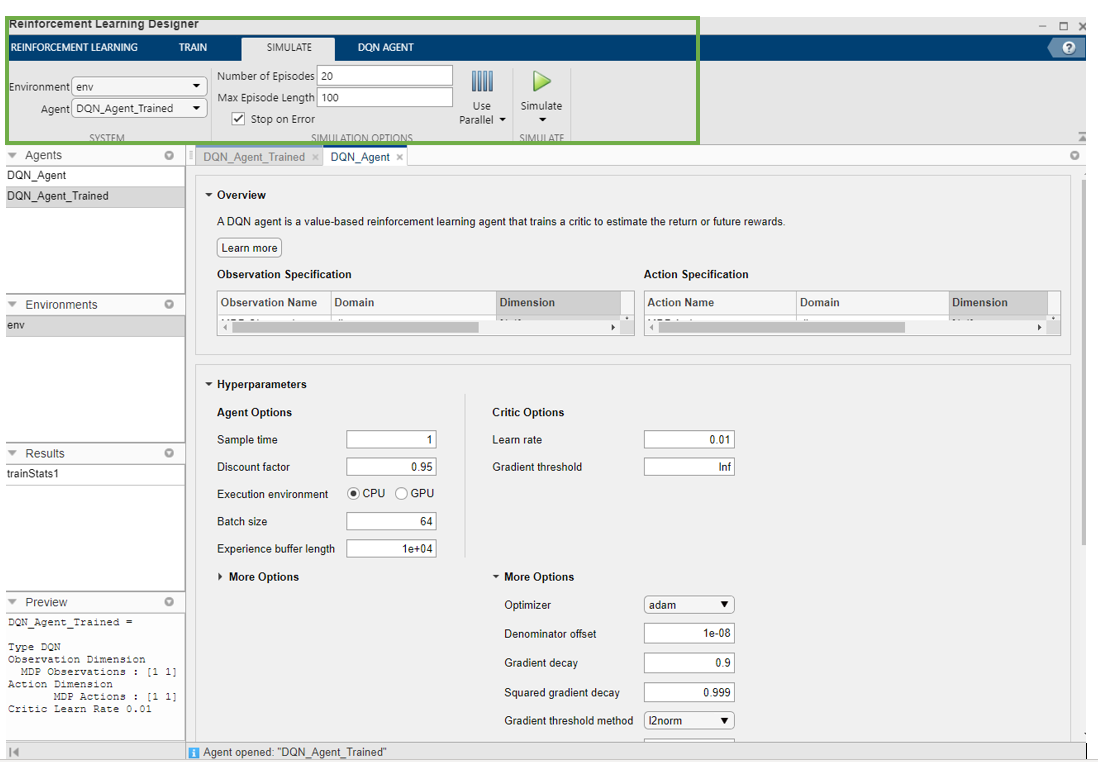

**Step 9:** Saving the trained agent in Workspace

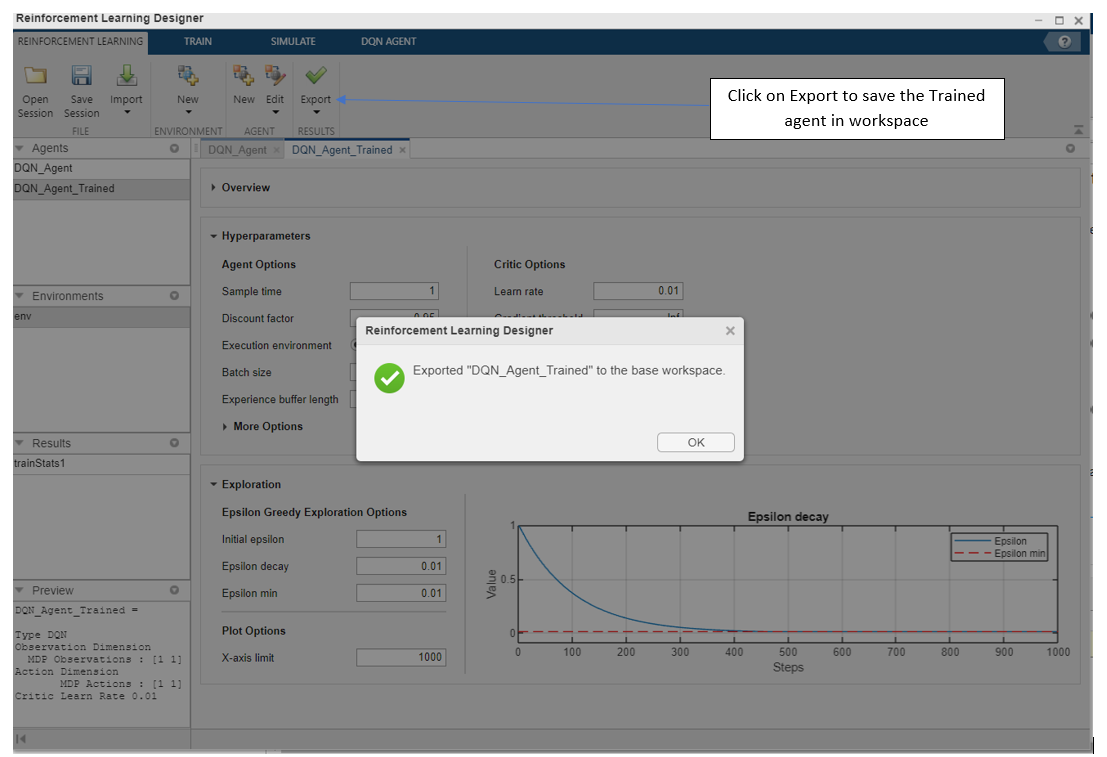

Let us analyze the trained network and extract the deep neural network from the critic.

Save the trained DQN_Agent_Trained in a variable named 'agent'

%Start code here ~ one line

%Code ends here

Use function [`getCritic(agent)`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.agent.rlqagent.getcritic.html#d123e5187)`. `This functions returns the critic representation object for the specified reinforcement learning agent.

%Start your code here ~ one line

%Code ends here

Now we obtain the hyper parameter of the trained using function `getLearnableParameters(critic)`

%Start your code here ~ one line

%Code ends here

In this module we learnt

- Limitations of tabular RL agents

- How Deep Neural Networks can be applied as a function approximator for RL agents

- How to use Reinforcement Learning Designer App to create and train an agent

In the next module to Custom build MATLAB environments

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: []